# Derivative of state '1' in block 'X/Y/Integrator' at time 0.55 is not finite

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_05_15_InfiniteDerivative/2024_05_15_InfiniteDerivative.prj)

Let's look at another frequently visited MATLAB Answers page:

[Derivative of state '1' in block 'X/Y/Integrator' at time 0.55 is not finite.](https://www.mathworks.com/matlabcentral/answers/252574-derivative-of-state-1-in-block-x-y-integrator-at-time-0-55-is-not-finite)

## The Problem

Here is a simple model similar to the one I have been using recently in multiple post.

mdl = "suspension";
open_system(mdl);

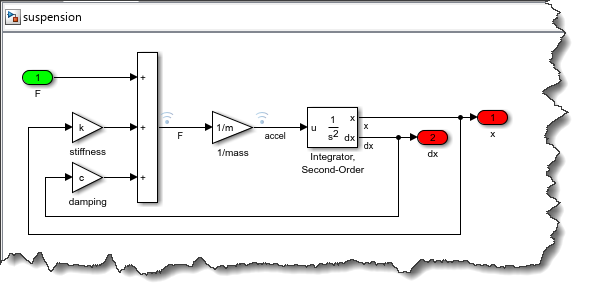

When simulating the model, we get the same error as reported on MATLAB answer:

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('Stoptime','500');
in = in.setModelParameter('CaptureErrors','on');
out= sim(in);
out.ErrorMessage

ans = 'Derivative of state 'dx' in block 'suspension/Integrator, Second-Order' at time 284.04767405115081 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)'

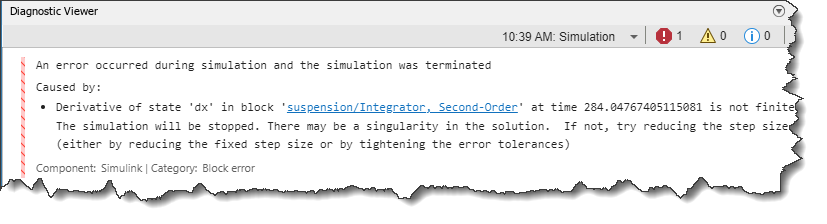

This error can be triggered by multiple reasons. Let's look at the most likely reasons.

## Unstable System

The most common reason for this error is that equations in the model are unstable. We can plot the state mentioned in the error message to see that it diverges toward infinity:

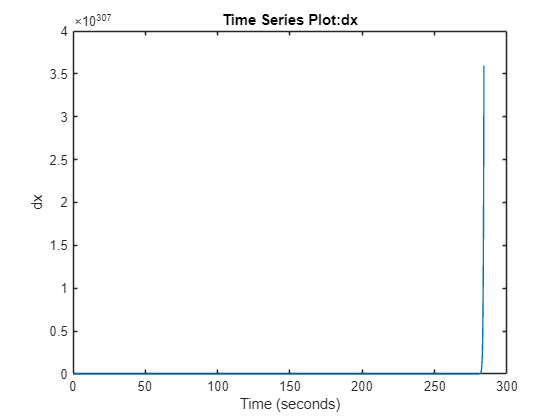

plot(out.xout.get('dx').Values)

In this simulation, the size of the model makes it easy to identify the problem. The signs specified in the Sum block result in a positive feedback loop.

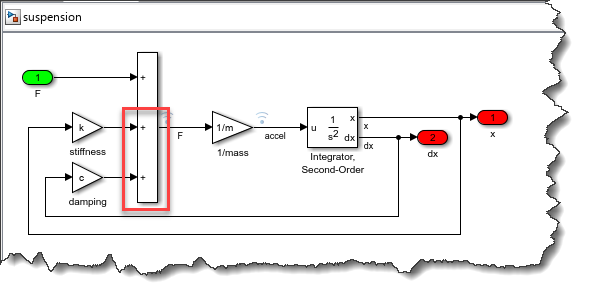

To solve the problem and make this model behave as intended, we need to make the two highlighted signs negative

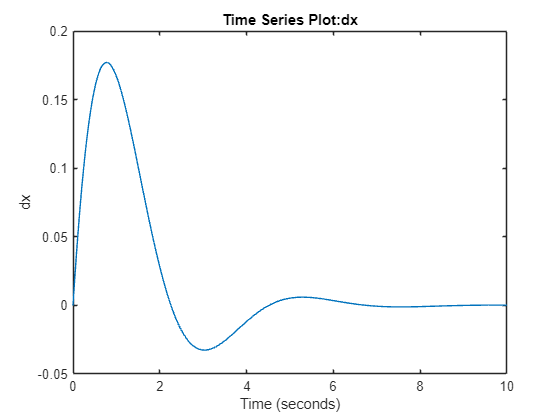

in = Simulink.SimulationInput(mdl);
in = in.setBlockParameter('suspension/Sum','Inputs','+--');
out = sim(in);
plot(out.xout.get('dx').Values)

Here are a few tips to help debugging this kind of issues.

#### Solver Profiler

Try simulating using the [Solver Profiler](https://www.mathworks.com/help/releases/R2024a/simulink/slref/solverprofiler.html):

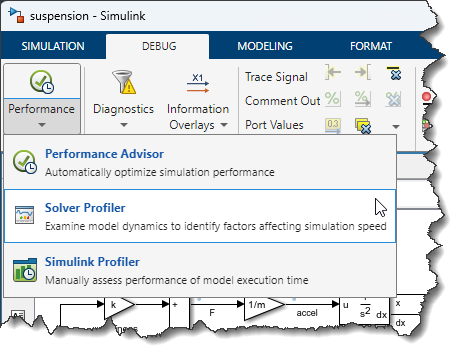

In the Explore Gallery, launch the States Explorer.

This will allow you to quickly scan all the states in the model and hopefully understand what is going wrong:

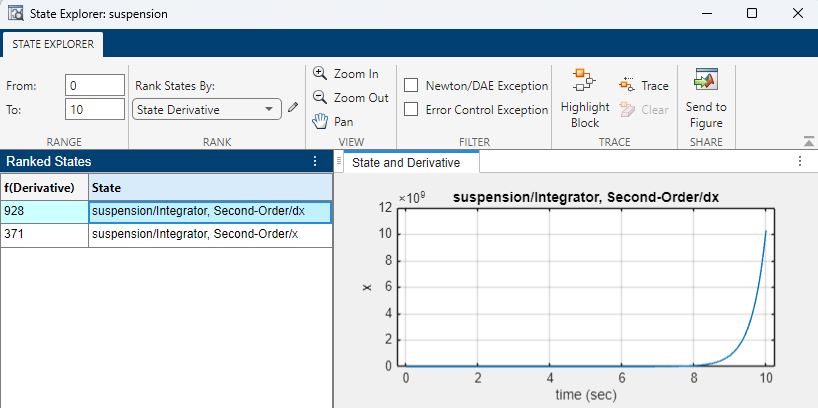

#### Highlight Source

Another useful tool is to [Highlight Signal to Source](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-signal-sources-and-destinations.html):

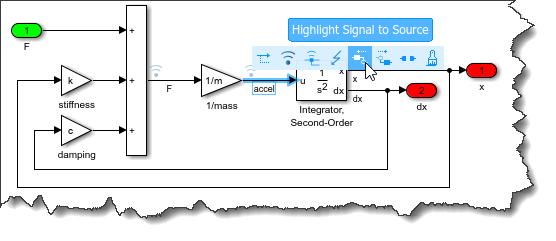

Once enabled, use the arrow keys to highlight the upstream blocks feeding the integrator and try understanding the logic making the equations unstable.

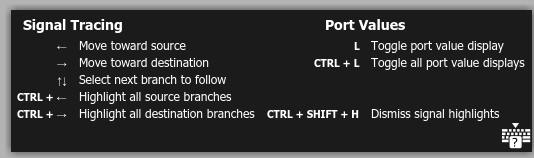

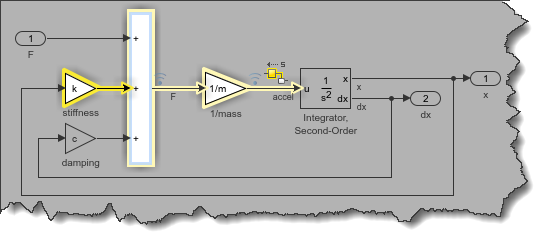

#### Simulink Debugger

The [Simulink Debugger](https://www.mathworks.com/help/releases/R2024a/simulink/simulation-stepper.html) allows you to step block by block during a simulation, which can be useful to diagnose this kind of issue.

First, select the blocks upstream of the block listed in the error message and enable [Port Value Display](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-block-outputs.html).

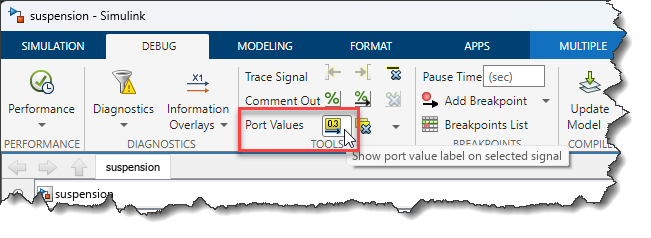

Select the signal entering the problematic block and add a breakpoint.

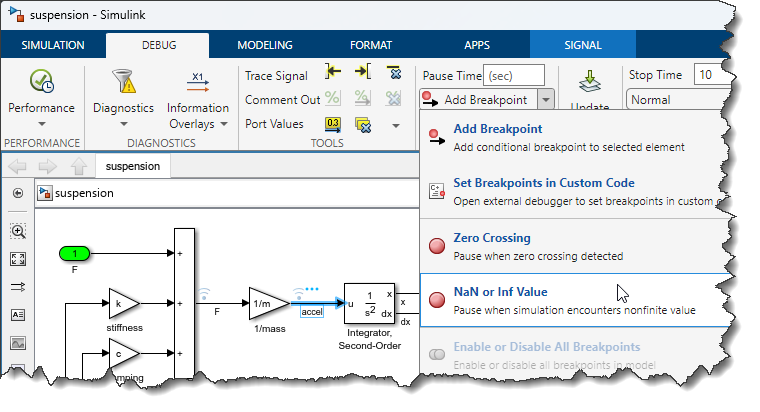

Click Run and when the breakpoint is hit, you will be able to step block by block to try identifying the problem with the equations in your model.

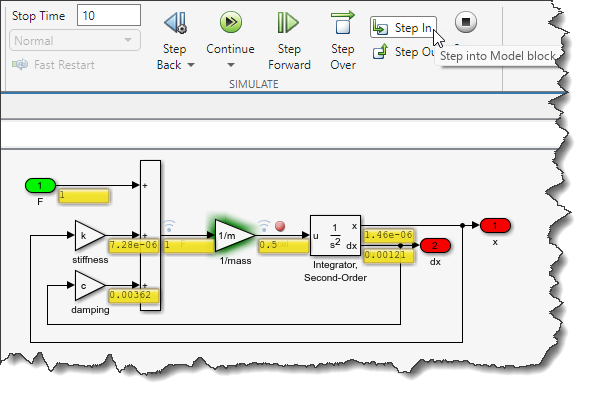

## Step size is too large

As described in the error message, one possible reason for this error is the solver taking to large steps. 

Here is a slightly different version of the model.

mdl = "suspensionFixedStep";
open_system(mdl);

I fixed the signs of the Sum block to make the equations stable, but I changed the solver to `ode3` with a step size of 1 second.

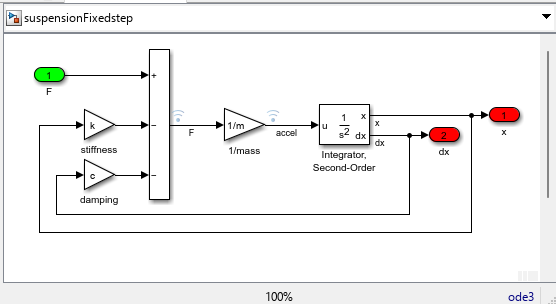

I will simulate the model with a large value for `k`, making the system dynamic very fast and impossible to capture properly with the step sized of 1 seconds.

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('CaptureErrors','on');
in = in.setVariable('k',1e5);
out = sim(in);
out.ErrorMessage

ans = 'Derivative of state 'dx' in block 'suspensionFixedStep/Integrator, Second-Order' at time 49.5 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)'

When getting this error with a fixed-step solver, what I recommend is simulating the model with a variable-step solver and see what step-size it takes. The [Solver Profiler](https://www.mathworks.com/help/releases/R2024a/simulink/slref/solverprofiler.html) can help with that. In this case, we can see that the variable-step solver needs to take steps slightly smaller than 0.01 second. 

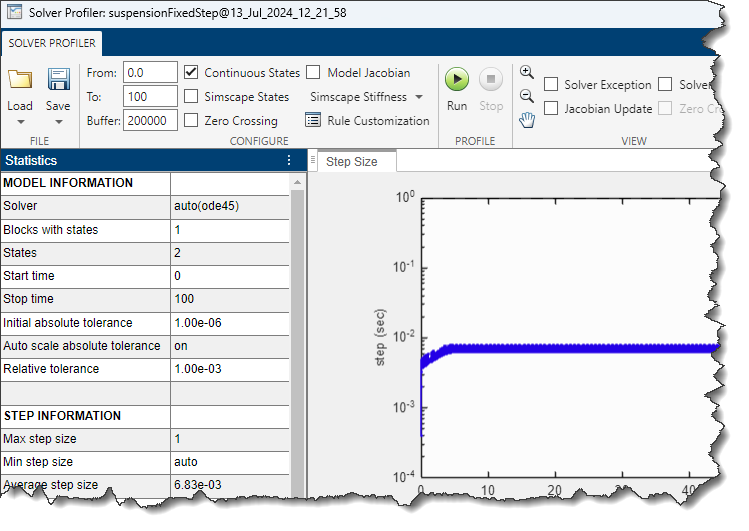

Let's try simulating the model with a fixed-step size of 0.005 second.

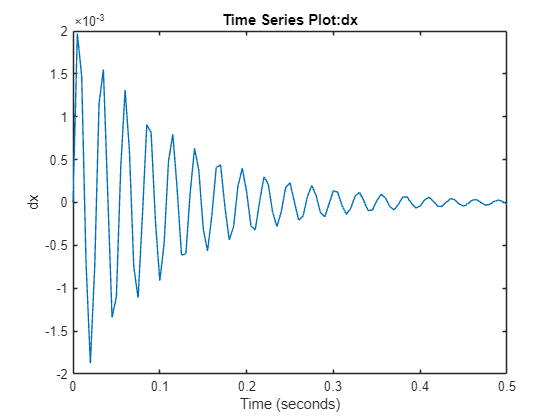

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('CaptureErrors','on');
in = in.setModelParameter('FixedStep','0.005');
in = in.setModelParameter('StopTime','0.5');
in = in.setVariable('k',1e5);
out = sim(in);
plot(out.xout.get('dx').Values)

## Division by Zero

This one might sound obvious, but if the equations in the model return `Inf` and this `Inf` is passed to an Integrator, you will get this error. One common reason for that is a division by zero.

mdl = "example3";
open_system(mdl);
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('CaptureErrors','on');
out = sim(in);
out.ErrorMessage

To diagnose this, I recommend using the Simulink Debugger as described above. Setting a breakpoint on `Inf` or `NaN` will stop the simulation at the first block where the Inf is generated.

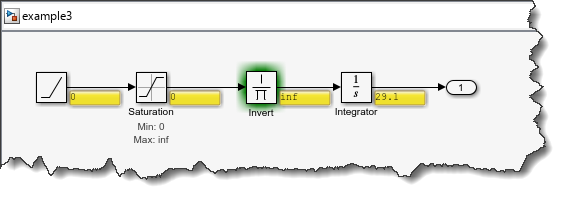

## Now it's your turn

Have you run into problems with this error? Let us know in the comments below.